# Create baseline network

%% Fresh 3-sector network
clear net
net = WirelessNetwork;

%% Channel sets
net.channel_sets = [4 3 3 4 3 3 4 3 3];
sum(net.channel_sets)

ans = 30


%% Generate 30 base stations
for i=1:30
    location = 600*rand + 1i*600*rand;
    first_sector = 3*randi(3)-2;
    channels = first_sector:(first_sector+2);
    power_dBm = 30 + 10*rand(1,3);
    net.AddBase(location, channels, power_dBm);
end

%% Check object
net

net =   WirelessNetwork with properties:

           bs_locations: [30×1 double]
            bs_channels: [30×3 double]
           bs_power_dBm: [30×3 double]
           channel_sets: [4 3 3 4 3 3 4 3 3]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


size(net.bs_channels)

ans =     30     3


size(net.bs_power_dBm)

ans =     30     3


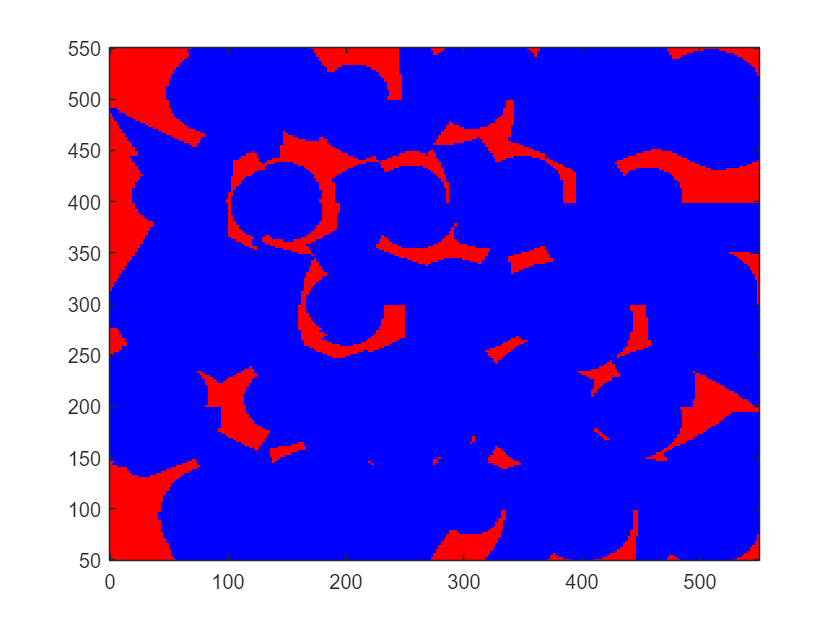

Covering 85.74 percent of the area with sufficient SINR
worst case SINR is -0.212277



%% Check maps and cost

net.MapSINR

net.ComputeCost

ans = 27500

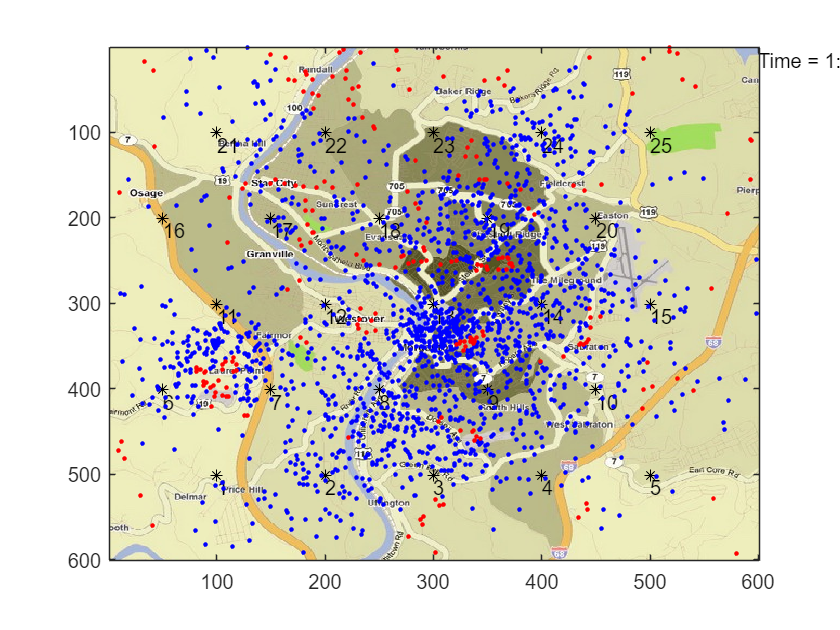

ans = struct with fields:
       cdata: [514×652×3 uint8]
    colormap: []


%% Load user data
load('MobileLocationData')

%% Show busy hour
net.MapCity(ms_locations{19})

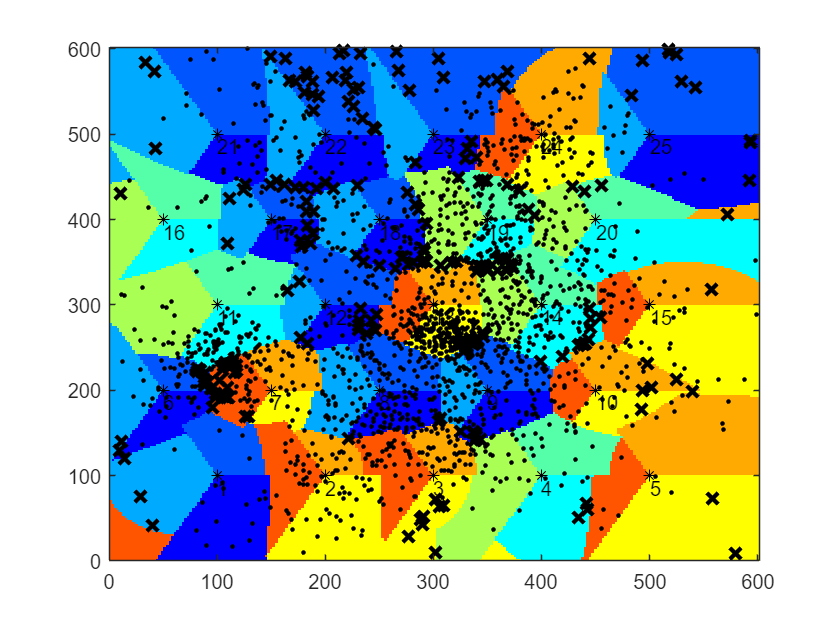

ans = struct with fields:
       cdata: [516×653×3 uint8]
    colormap: []


net.MapMobiles(ms_locations{19})


%% Analyze network
[num_connected, num_over_thresh] = net.AnalyzeNetwork(ms_locations);


sum(num_connected)

ans = 20192

percent_connected = sum(num_connected)/sum(call_attempts);
fprintf('The percentage connected is %2.2f%%\n', 100*percent_connected)

The percentage connected is 76.05%


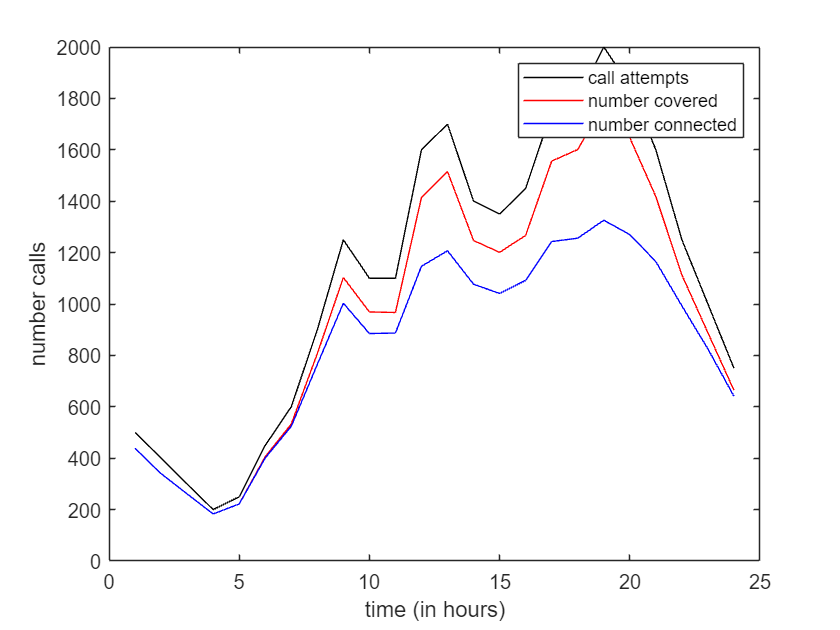


plot( 1:length(call_attempts), call_attempts, '-k', ...
    1:length(call_attempts), num_over_thresh, '-r', ...
    1:length(call_attempts), num_connected, '-b' );
xlabel( 'time (in hours)' );
ylabel( 'number calls' );
legend( 'call attempts', 'number covered', 'number connected' );

net.bs_power_dBm

ans =     30
    30
    30
    30
    30
    30
    30
    30
    30
    30


net.bs_locations(1)= 100+100i;
net.bs_locations(2)= 200+100i;
net.bs_locations(3)= 300+100i;
net.bs_locations(4)= 400+100i;
net.bs_locations(5)= 500+100i;

net.bs_locations(6)= 50+200i;
net.bs_locations(7)= 150+200i;
net.bs_locations(8)= 250+200i;
net.bs_locations(9)= 350+200i;
net.bs_locations(10)= 450+200i;

net.bs_locations(11)= 100+300i;
net.bs_locations(12)= 200+300i;
net.bs_locations(13)= 300+300i;
net.bs_locations(14)= 400+300i;
net.bs_locations(15)= 500+300i;

net.bs_locations(16)= 50+400i;
net.bs_locations(17)= 150+400i;
net.bs_locations(18)= 250+400i;
net.bs_locations(19)= 350+400i;
net.bs_locations(20)= 450+400i;

net.bs_locations(21)= 100+500i;
net.bs_locations(22)= 200+500i;
net.bs_locations(23)= 300+500i;
net.bs_locations(24)= 400+500i;
net.bs_locations(25)= 500+500i;





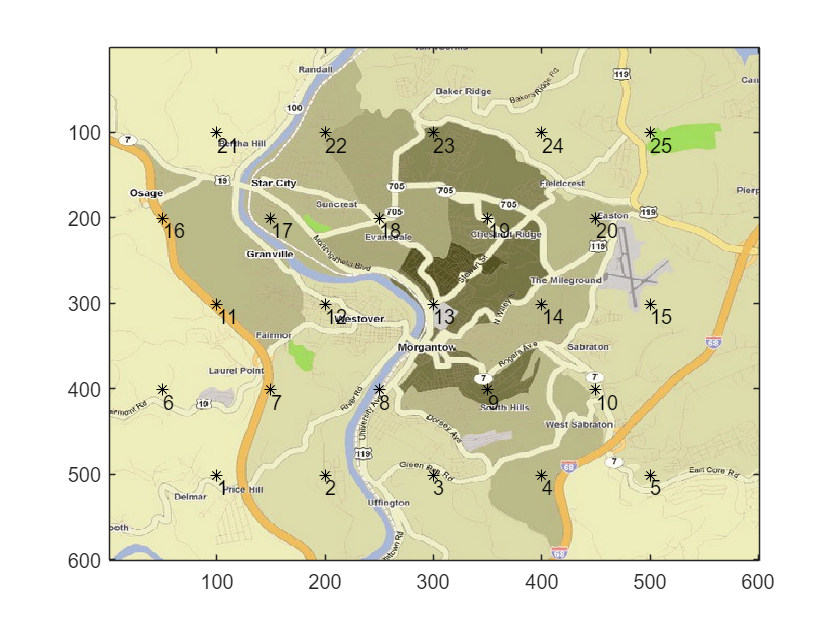

ans = struct with fields:
       cdata: [514×652×3 uint8]
    colormap: []


net.MapCity

net.ComputeCost

ans = 27500